# SC42025 Filtering & Identification

**PRACTICAL ASSIGNMENT II**

**Instructions: Fill in the live script with your code and answers. Then export the live script as a pdf (in the 'Live Editor tab', click on the arrow under 'Save' and then 'Export to pdf'). Hand in one report per group before the deadline.**

**DEADLINE**: 

## Introduction

In this practical assignment you will use your model-estimation code from Homework Assignments 3 & 4  to identify an unknown system by going through the system identification cycle. For this, you need the file `exciteSystem.p`, which you can find on Brightspace. Note that this file requires the `System Identification Toolbox. `You may consider this file as an **unknown black box system**. You can provide an input sequence and a sampling frequency to this system and it will return a corresponding output sequence at the specified sampling frequency.

The file is used by adding it to your path in MATLAB and calling the function

`y = exciteSystem(STUDENTID,u,fs)`

Here, `y` is the output sequence $$y_k$$ of the to be identified system, `STUDENTID` is the **lowest-valued** student-id of the students in the group, `u` is the provided input sequence $u_k$, and` fs` is the sampling frequency. 

The system is inherently simulated in discrete time, so there is **no need for you to apply a band-pass filter to prevent anti-aliasing**, as you need to do for analog systems that have been sampled digitally. Your objective is to identify a model for this black box system. Try to determine a model that performs well on both your identification as your validation data set in terms of simulation.

It can be expected that non-Gaussian sensor noise (noise spikes) will be present in the output. These spikes need to be removed from the data before identifying the system. 

Your system may also contain a time delay. This should also be taken into account before using your identification code.

To complete this assignment, we expect you to go trough the identification cycle, see the figure below, as many times as needed.

*Throughout this practical assignment, remember that the identification cycle is an iterative process and you typically need more than one iteration. Limit your report to the final iteration.*

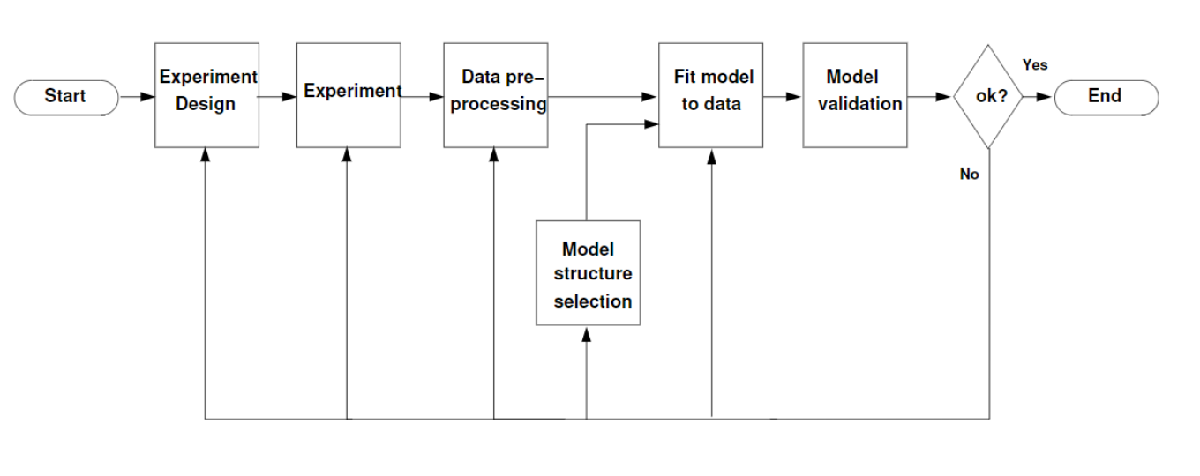

## Part 0: Setup

Please insert your names and student numbers below.

Name: Mihaly Fey

Student Number: 5476747;

Name: Jodok Dittmann

Student Number:

% Clear workspace
clearvars; clc; close all;

% Insert the lowest-valued student-id of the students in the group;
STUDENTID = 5476747;

## Part 1: Experiment Design and Data Pre-Processing

The first steps of the identification cycle are to design your experiment and pre-process the input and output data. In this exercise, use the `exciteSystem` function to

Determine a suitable sampling frequency and motivate your answer.

*Answer**:*

*First a suitably high input size had to be found, so sensor noise plays little role in identification. Then the open loop rise time was measured at 4.9439 seconds in a simulation with no spike during the corresponding part in the transients. Taking the sampling the sampling time as 10 times that gives 0.494 seconds. *

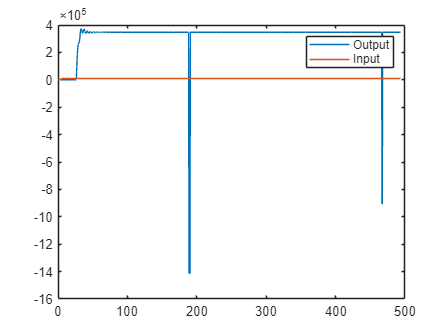

N = 1000;
steptime = 10;
A = 10000;
u1 = ones(1, N)*A;
u1(1:steptime) = zeros(steptime,1);
Ts = 0.494;
fs = 1/Ts;
t = (0:N-1)*Ts;

system = @(u) exciteSystem(STUDENTID, u, 1/Ts);

y1 = system(u1);

plot(t, y1)
hold on
stairs(t, u1)
legend('Output','Input')
hold off

Design a persistingly exciting input signal. Show how you determined the order of persistency of excitation.  Furthermore, you are **not allowed** to use a white-noise sequence as an input signal, as this is often not possible in the real-world.

*Answer**:*

*The order of a persistently exciting signal is the highest *`s`* for which an N exists, for which the following statement holds:*


$$\Phi_N = \pmatrix{u_0 & u_1 & \dots & u_{s-1} \cr
u_1 & u_2 & \dots & u_{s} \cr
    \vdots & \vdots & & \vdots \cr
    u_{N-s+1} & u_{N-s+2} & \dots & u_{N-1} }$$


*This matrix gives has the highest possible rank for a given input length N,  when N= 2s-1, so an upper limit for the order of the signal is half of its length. Then the rank of the Hankel matrix of a generated input signal should be half of its length to be persistently exciting.*

u2 = prbs(10,N)'*A;

N/2 == rank(hankel(u2(1:N/2), u2(N/2:end)))

ans = logical
   1


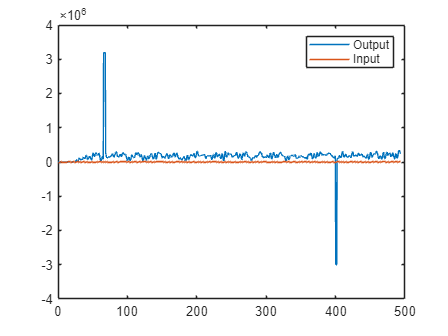


order = (N)/2;

y2 = system(u2);

plot(t, y2)
hold on
stairs(t, u2)
legend('Output','Input')
hold off

Motivate how you identify and remove spike noise from your data.*You may use the Matlab function *`interp1`* to do the interpolation. *Plot a figure of the output signal before and after spike removal.

*Answer**:*

*Data points are classified as outliers if the data value is at least 40 times the input amplitude, which in this case is of the pseudo random binary sequence.*

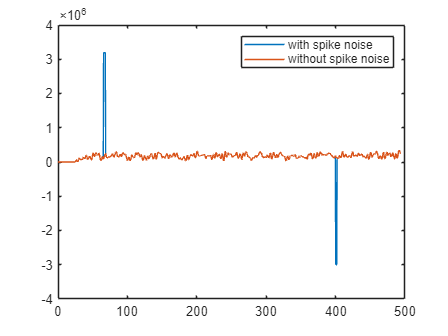

y3 = denoise(y2,A);

plot(t, y2, t, y3)
legend('with spike noise','without spike noise')

Determine any time-delays of your system. Correct the input and output data to account for the determined time-delay by introducing an appropriate time-shift.

*Answer**:*

*The time delay is the index of the first value, where output can be differentiated from sensor noise, which is 43 timesteps in this case.*

y4 = denoise(y1,A);

epsilon = 50;

delay = find(y4 > epsilon, 1) - steptime - 2;

tau = delay*Ts

tau = 21.2420

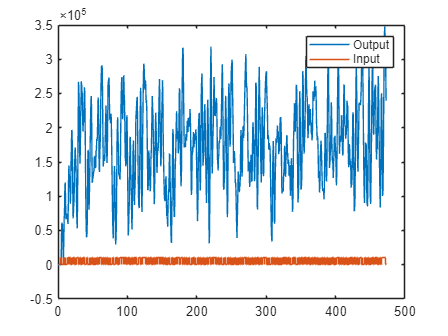


u5 = u2(1:end-delay+1);
y5 = y3(delay:end);
t = t(1:end-delay+1);

plot(t, y5)
hold on
stairs(t, u5)
legend('Output','Input')
hold off

Remove the DC offset from the output (if any).

*Answer**:*

*The DC offset will be the reponse to a 0 input, which the time region before the delay in the step input. Averaging this to filter the sensor noise the offset varies between 4-5 d from run ro run.*

offset = mean(y3(1:delay+1))

offset = 4.9013


y6 = y5 - offset;

Determine whether your system is (approximately) linear by means of an experiment. Plot a figure of the experiment that you used and use this figure to motivate your conclusions.

*Answer**:*

*The two plots show the additivity and scaling property of linear systems. The small mismatch at some datapoints can be explained by sensor noise. *

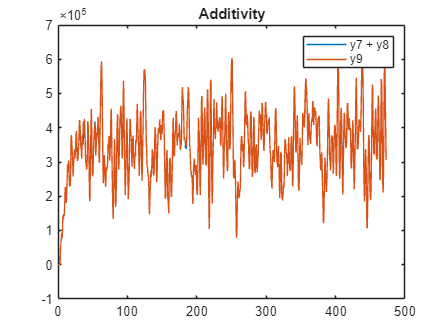

u7 = (prbs(7,N))'*A;

% Additivity
[y7, ~] = preprocess(u7, delay, A, STUDENTID, Ts);
[y8, ~] = preprocess(u2, delay, A, STUDENTID, Ts);
[y9, ~] = preprocess(u2+u7, delay, 2*A, STUDENTID, Ts);

plot(t, y7 + y8, t, y9)
legend('y7 + y8','y9')
title('Additivity')

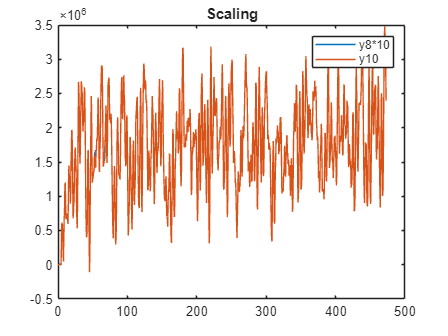


% Scaling
[y10, ~] = preprocess(10*u2, delay, 10*A, STUDENTID, Ts);
plot(t, y8*10, t, y10)
legend('y8*10','y10')
title('Scaling')

Generate output data that you will use for identification using your persistently exciting input signal. Also generate new data that you will use for validation.

*Answer**:*

*For traing and validation data one 1000 timeddstep long simulation was done using a Pseudo-random binary sequence, generated with order 10. Of the response data the last 1/3 was kept for validation and the first 2/3 was used for training. *

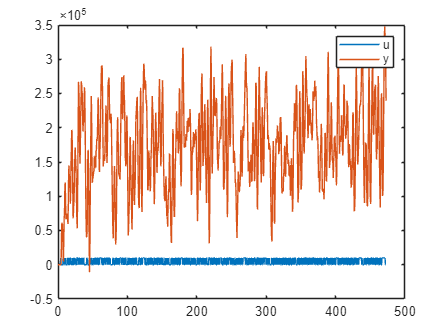

u = (prbs(10,N))'*A;


[y, u] = preprocess(u, delay, A, STUDENTID, Ts);
    
end_train = floor(length(y)*2/3); 

y_train = y(1:end_train);
u_train = u(1:end_train);

y_val = y(end_train+1:end);
u_val = u(end_train+1:end);

plot(t, u, t, y)
legend('u','y')

## Part 2: Identification

You will now identify your system using the data that you generated in Part 1. Here, we highly recommend you to use your code from Homework Assignments 3 & 4. It is however **not allowed** to use tools from the `System Identification Toolbox` to identify your system.

Determine the model order. Plot the singular values using the `semilogy` command and motivate your choice of order.

*Answer**:*

*The elbow in  the SVD plot is at n=7, meaning there are 6 significant "modes in the system. It is therefore logical to choose 6 as the model order. *

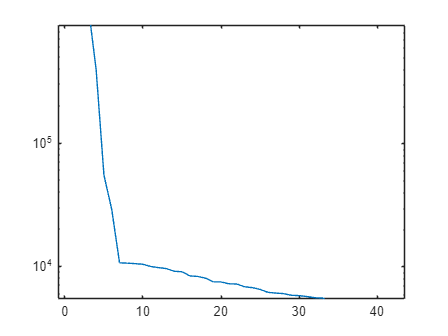


s = 100;

U_hankel = hankel(u_train(1:2*s),u_train(2*s:end_train));
Y_hankel = hankel(y(1:2*s),y(2*s:end_train));

L = qr([U_hankel(s+1:2*s,:);U_hankel(1:s,:);Y_hankel]',0)';
 ))


n = 3;

Identify the model. You are free to choose the identification method.

*Answer**:*

*For identification a past-output MOESP method was used, with the model order set to 6.*

[A,B,C,D,x0] = pomoesp(u_train,y_train,s,n)

A =     0.8635    0.4515   -0.0752
   -0.3039    0.6674   -0.5353
   -0.0442    0.4056    0.8228


B =    -8.9958
   -6.9715
    1.0810


C =    -0.3988    0.4281    0.1465


D = -0.2409

x0 = 1.0e+04 *

   -1.1449
    0.0344
    1.1816


## Part 3: Validation

The final step of the system identification cycle is to validate your model. In this part you will validate your identified model using validation data that was **not** used during identification. 

Compare and discuss the VAF for the identification data with the VAF for the validation data.

*Answer**:*

*The VAF on the identification data is 94%, while on the validation data is 92%, which means that it is high on both sets. This means that while the fit is slightly better on the training data, it is not under or overfitted. *

[y_sim,~] = simsystem(A,B,C,D,x0,u);

vaf_val = VAF(y_val,y_sim(end_train+1:end))

vaf_val = 99.4437

vaf_train = VAF(y_train, y_sim(1:end_train))

vaf_train = 99.0891

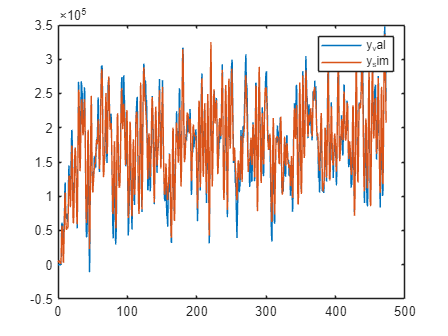


 
plot(t, [y_train; y_val], t, y_sim)
legend('y_val','y_sim')

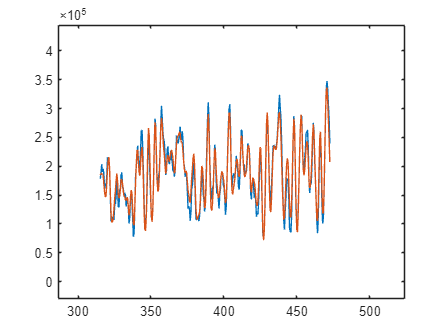


plot(t(end_train+1:end), y_val, t(end_train+1:end), y_sim(end_train+1:end));

Determine and discuss the auto-correlation of the residuals.

*Answer**:*

*The auto-correlation of the signal shows a spike at 0 and is constant 10% of that everywhere else, which means that the signal is approximately a zero mean white noise, which points to the identfied model having a zero-mean error. *

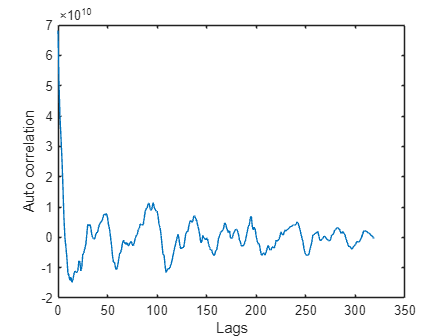

% [y_sim2,~] = simsystem(A,B,C,D,x0, u(end_train+1:end));
residuals = y_val - y_sim(end_train+1:end);

[acf, lags] = xcorr(residuals, residuals);
plot(lags(320:end), acf(320:end));
ylabel("Auto correlation");
xlabel("Lags");


disp(acf(320));

   6.8098e+10



Determine and discuss the cross-correlation between the residuals and the inputs.

*Answer**:*

*The cross-correlation slowly tends to 0 as the lags increase, but there is an overshoot at the very start, which points to the inputs always undershooting the inpulse responses but then making up for it, and then the decay is a bit slower then in the system. As there is a peak at 0 here as well, the errors can also be thought as some random process which does tend to 0 over time. *

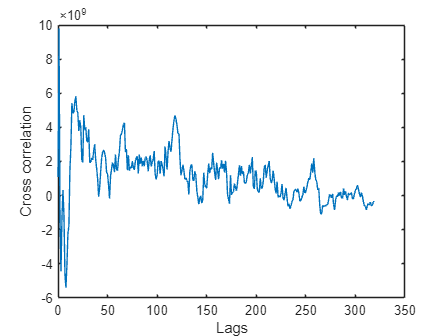

[ccf, lags] = xcorr(-residuals, u(end_train+1:end));
plot(lags(320:end), ccf(320:end));
ylabel("Cross correlation");
xlabel("Lags");

disp(ccf(320));

   1.0887e+09



**Is your model OK? If not, return to Part 1 and Part 2 for the next iteration. **

Overall the high VAF, the ZMWN errors and the residual-input correlation the approximated model is adequate.

## Functions

Implement your functions in this section

### Spike Removal

function Y = denoise(y, A)
    N = length(y);
    z = zeros(1,N);
    for i = 1:N
       if abs(y(i)) > 40*A
          z(i) = 1;
      end
    end
    v = 1:N;
    Y = interp1(v(~z),y(~z),v,"pchip")';
end

### Preprocessing

function [Y, U] = preprocess(u, delay, A, STUDENTID, Ts)
    y = exciteSystem(STUDENTID, u, 1/Ts);
    y = denoise(y, A);
    y = y - mean(y(1:delay+1));
    U = u(1:end-delay+1);
    Y = y(delay:end);
end

### Prediction Error Methods

Implement your PEM functions below 

%YOUR CODE HERE

### Subspace ID Methods

Implement your Subspace ID functions below 

function [A,B,C,D,x0]=pomoesp(u,y,s,n)

N = length(u);

U_hankel = hankel(u(1:2*s),u(2*s:N));
Y_hankel = hankel(y(1:2*s),y(2*s:N));

L = qr([U_hankel(s+1:2*s,:);U_hankel(1:s,:);Y_hankel]',0)';
L_32 = L(3*s+1:4*s,s+1:3*s);

l = 1;
[U, ~, ~] = svd(L_32,"econ");

C = U(1:l,1:n);
A = U(1:(s-1)*l,1:n)\U(l+1:end,1:n);

m = 1;
O = zeros(l*N,n);
P = zeros(l*N,n*m);

for k=1:N
    O(k,:) = C*A^(k-1);
    if k < N
        for j = 1:k
            P(k+1,:) = P(k+1,:)+C*A^(k-j)*u(j);
        end
    end
end

Phi = [O, P, u];
x0BD=Phi\y;
x0=x0BD(1:n);
B=x0BD(n+1:2*n);
D = x0BD(2*n+1);
end

### Simulation 

function [y,x] = simsystem(A,B,C,D,x0,u)

[n, ~] = size(B); 
[l, ~] = size(C); 
N = size(u, 1);   

x = zeros(N, n);
y = zeros(N, l);

x(1, :) = x0';

for k = 1:N
    y(k, :) = (C * x(k, :)' + D * u(k, :)')';
    if k < N
        x(k + 1, :) = (A * x(k, :)' + B * u(k, :)')';
    end
end
end

### VAF

function vaf = VAF(y,yhat)

N = length(y);
   
var_e = sum((y - yhat).^2)/N;

var_y =  sum(y.^2)/N;

vaf = 100*(1 - var_e/var_y);

end